## **Driver test program to check Clothoids library**

**Biarcs**

MATLAB and proposed biarc on the same data

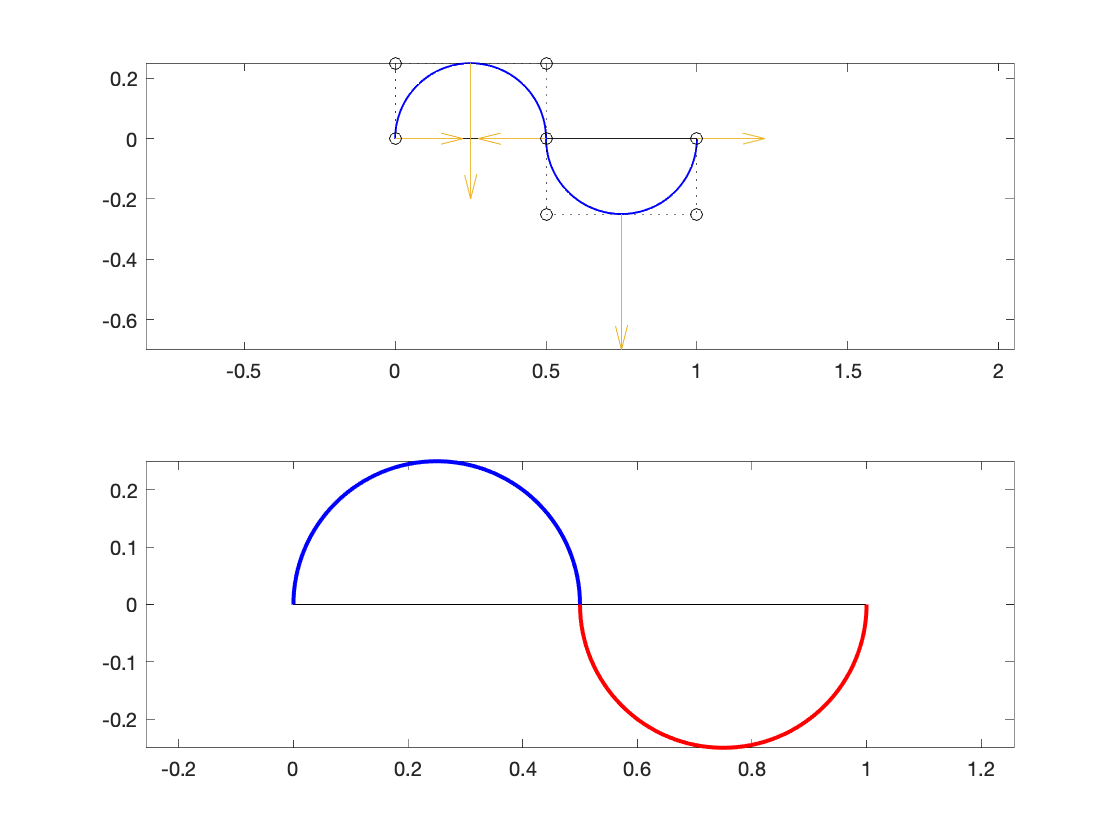

x0=0; y0=0; x1=1; y1=0;
theta0=pi/2-1e-5;
theta1=pi/2-1e-5+20*pi;

a0=theta0+pi/2;
a1=theta1+pi/2;

p=[x0,x1;y0,y1]; u=[cos(a0),cos(a1);sin(a0),sin(a1)];

subplot(2,1,1);
plot(p(1,:),p(2,:),'k')
hold on
bi_arc = fnrfn(rscvn(p,u),[0.5,1.5]);
bspline_plot(bi_arc,true);
axis equal
hold off

subplot(2,1,2);
plot(p(1,:),p(2,:),'k')
hold on
L1 = Biarc(x0,y0,theta0,x1,y1,theta1);
L1.plot();
axis equal
hold off